Lista 04 - Análise da Estabilidade em tempo discreto 

Aluno: Vitor Augusto Tibério - 14658834 - Eng. Elétrica - EESC/SUP

Prof. Dr. Marcos Rogério Fernandes

## Atividade 01 - Transformada Z de um Sinal

Questão (1)

close all;
clear all; 
clc; 
syms n;
f = 1 + n*(1/3)^n;

$$f = {\left(\frac{1}{3}\right)}^{n}\,n+1$$

z = ztrans(f);

$$z = \frac{z}{z-1}+\frac{3\,z}{{\left(3\,z-1\right)}^{2}}$$

pretty(z);

  z         3 z
----- + ----------
z - 1            2
        (3 z - 1)



Questão (2)

close all; 
clear all; 
clc;
syms n;
f = (1/2)^n + n*(1/5)^n
z = ztrans(f)
pretty(z);

Questão (3)

close all; 
clear all; 
clc; 
syms n a T;
f = exp(a*n*T)

$$f = {\mathrm{e}}^{T\,a\,n}$$

z = ztrans(f)

$$z = \frac{z}{z-{\mathrm{e}}^{T\,a}}$$

pretty(z);

      z
------------
z - exp(T a)



Questão (4)

close all; 
clear all; 
clc; 
syms n T
f = n*T

$$f = T\,n$$

z = ztrans(f)

$$z = \frac{T\,z}{{\left(z-1\right)}^{2}}$$

pretty(z)

   T z
--------
       2
(z - 1)



## Atividade 02 - Transformada Z Inversa

*obs: Quando aplica-se a transformada Z inversa, obtém-se a função com o tempo discreto. A mesma está sendo representada por y[t].

Questão (1)

close all 
clear all 
clc
syms z 
F = 1/z

$$F = \frac{1}{z}$$

f = iztrans(F)

$$f = \delta_{n-1,0}$$

pretty(f)

kroneckerDelta(n - 1, 0)



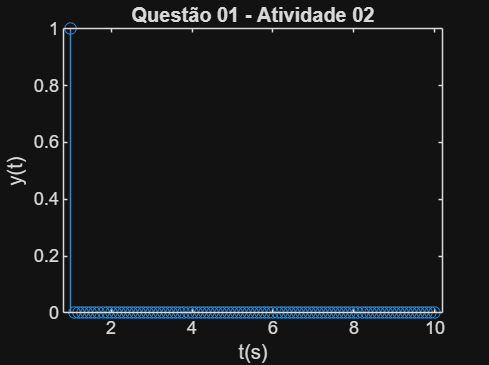

td = 1:0.1:10;
figure
stem(td, subs(f, 'n', td))
title('Questão 01 - Atividade 02')
xlabel('t(s)')
ylabel('y[t]')

Questão (2)

close all 
clear all 
clc 
syms z 
F = (z+2)/((z-1/3)*(z-1/4))

$$F = \frac{z+2}{\left(z-\frac{1}{3}\right)\,\left(z-\frac{1}{4}\right)}$$

f = iztrans(F)

$$f = 84\,{\left(\frac{1}{3}\right)}^{n}-108\,{\left(\frac{1}{4}\right)}^{n}+24\,\delta_{n,0}$$

pretty(f)

   / 1 \n       / 1 \n
84 | - |  - 108 | - |  + 24 kroneckerDelta(n, 0)
   \ 3 /        \ 4 /



td = 1:0.1:10

td =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


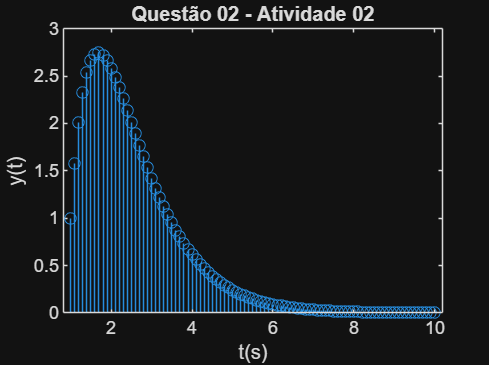

figure
stem(td, subs(f, 'n', td))
title('Questão 02 - Atividade 02')
xlabel('t(s)')
ylabel('y[t]')

Questão (3)

close all 
clear all 
clc 
syms z 
F = (5*z)/(z-1/2) + (2*z)/((z-1/9)^2)

$$F = \frac{5\,z}{z-\frac{1}{2}}+\frac{2\,z}{{\left(z-\frac{1}{9}\right)}^{2}}$$

f = iztrans(F)

$$f = 5\,{\left(\frac{1}{2}\right)}^{n}+18\,{\left(\frac{1}{9}\right)}^{n}+18\,{\left(\frac{1}{9}\right)}^{n}\,\left(n-1\right)$$

pretty(f)

  / 1 \n      / 1 \n      / 1 \n
5 | - |  + 18 | - |  + 18 | - |  (n - 1)
  \ 2 /       \ 9 /       \ 9 /



td = 1:0.1:10

td =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


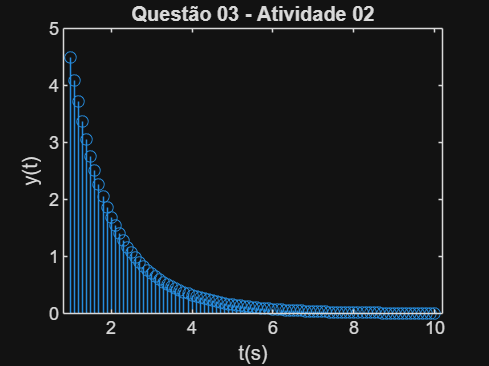

figure
stem(td, subs(f, 'n', td))
title('Questão 03 - Atividade 02')
xlabel('t(s)')
ylabel('y[t]')

Questão (4)

clear all 
close all 
clc 
syms z
F = (5*z*(z-cos(5)))/(z^2 - 2*cos(5)*z +1);

$$F = \frac{5\,z\,\left(z-\frac{5110003651005145}{18014398509481984}\right)}{z^{2}-\frac{5110003651005145\,z}{9007199254740992}+1}$$

f = iztrans(F);

$$f = 5\,{\left(-1\right)}^{n}\,\cos\left(n\,\left(\pi -\mathrm{acos}\left(\frac{5110003651005145}{18014398509481984}\right)\right)\right)$$

pretty(f)

      n    /   /          /  5110003651005145 \ \ \
5 (-1)  cos| n | pi - acos| ----------------- | | |
           \   \          \ 18014398509481984 / / /



td = 1:0.1:10;

td =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000


figure
stem(td, subs(f, 'n', td))

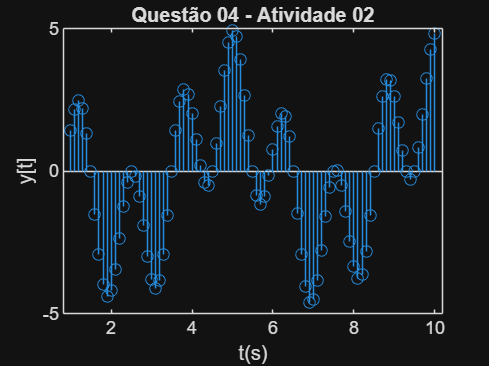

title('Questão 04 - Atividade 02')
xlabel('t(s)')
ylabel('y[t]')

Questão (5)

clear all 
close all 
clc 
syms z 
F = 3*z/(3*z-2)

$$F = \frac{3\,z}{3\,z-2}$$

f = iztrans(F)

$$f = {\left(\frac{2}{3}\right)}^{n}$$

pretty(f);

/ 2 \n
| - |
\ 3 /



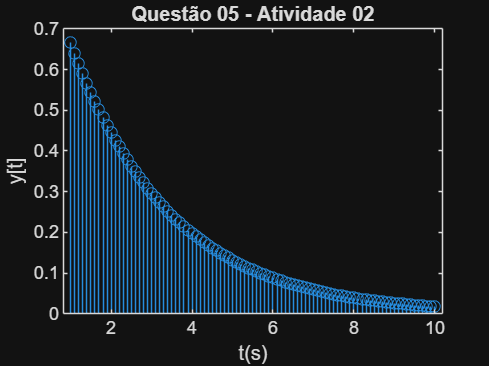

td = 1:0.1:10;
figure;
stem(td, subs(f, 'n', td));
title('Questão 05 - Atividade 02');
xlabel('t(s)');
ylabel('y[t]');

## Atividade 03 - Frações Parciais

Questão (1)

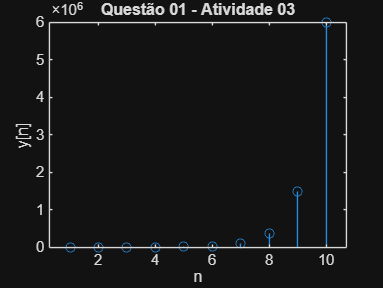

close all 
clear all 
clc 
format rational 
num = [1 2];
den = conv([1 -3],[1 -4]);
[r, p] = residuez(num, den);

syms z 
F = r(1)*z / (z-p(1)) + r(2)*z / (z-p(2));
f = iztrans(F);
t = 1:10;
fn = subs(f, 'n', t);
figure;
stem(t, fn)
title('Questão 01 - Atividade 03');
ylabel('y[n]');
xlabel('n');

Questão (2)

close all 
clear all 
clc 
format rational 
num = [1 1 5 0];
den = [1 -31/36 5/24 -1/72];
[r, p] = residuez(num, den)

r =      414/7     
    -153       
     664/7     


p =        1/2     
       1/4     
       1/9     


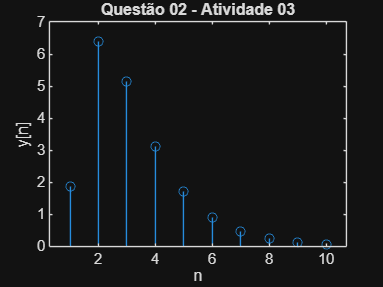


syms z 
F = r(1)*z / (z-p(1)) + r(2)*z / (z-p(2)) + r(3)*z / (z-p(3));
f = iztrans(F);
t = 1:10;
fn = subs(f, 'n', t);
figure;
stem(t, fn)
title('Questão 02 - Atividade 03');
ylabel('y[n]');
xlabel('n');

Questão (3)

close all 
clear all 
clc 
format rational 
num = 5*conv([1 -1/3],[1 -1/5]);

num =        5             -8/3            1/3     


den = conv(conv([1 -1/2], [1 -1/2]), [1 -1/9]);

den =        1            -10/9           13/36          -1/36    


[r,p] = residuez(num, den);

syms z 
F = r(1)*z / (z-p(1)) + r(2)*z / (z-p(2)) + r(3)*z / (z-p(3));
f = iztrans(F);
t = 1:10;
fn = subs(f, 'n', t);
figure;
stem(t, fn)

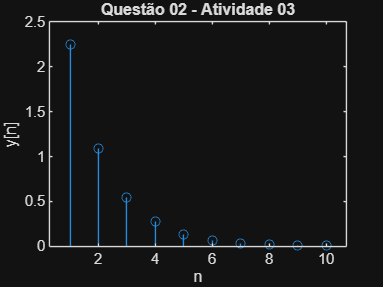

title('Questão 02 - Atividade 03');
ylabel('y[n]');
xlabel('n');

Questão (4)

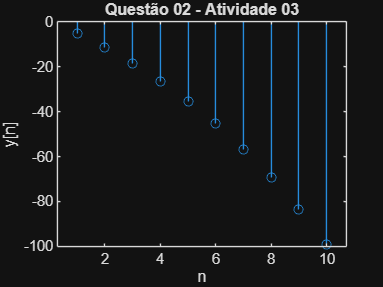

close all
clear all
clc 
format rational 
num = [1 -7 0];                 
den = [1 -25/12 25/24 1/24];
[r,p] = residuez(num, den);

syms z 
F = r(1)*z / (z-p(1)) + r(2)*z / (z-p(2)) + r(3)*z / (z-p(3));
f = iztrans(F);
t = 1:10;
fn = subs(f, 'n', t);
figure
stem(t, fn)
title('Questão 02 - Atividade 03');
ylabel('y[n]');
xlabel('n');

Questão (5)

clear all 
close all 
clc
format rational
num = [3 0 10];                 
den = poly([0.4 0.4 0.4]);    
[r,p] = residuez(num, den);

syms z 
F = r(1)*z / (z-p(1)) + r(2)*z / (z-p(2)) + r(3)*z / (z-p(3));
f = iztrans(F);
t = 1:10;
fn = subs(f, 'n', t);
figure;
stem(t, fn);

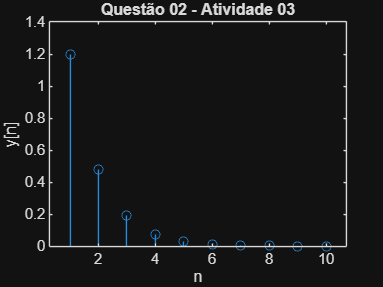

title('Questão 02 - Atividade 03');
ylabel('y[n]');
xlabel('n');

## Atividade 04 - Ganho Crítico

Questão (1)

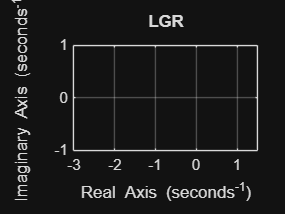

close all 
clear all 
clc 
Gd = tf([0.05268 0.01052], [1 -1.541 0.5408]);
rlocus(Gd);
zgrid
title('LGR')
axis equal 

Kc = margin(Gd)

Kc = 29.2525

Pelo comando Margin, Kc = 29.2525. Logo, pode-se avaliar a resposta ao degrau para as 3 situações possíveis: K = Kc, K < Kc e K > Kc. Com isso, tem-se o seguinte código:

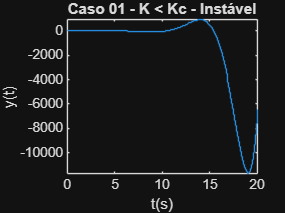

%% Situação 01 - K < Kc
T = 0.1; 
t = 0:T:20;
K = 10; 
Gf1 = K*Gd / (1 + K*Gd);
[y1, t] = step(Gf1, t);
figure
stairs(t, y1)
title('Caso 01 - K < Kc - Instável')
xlabel('t(s)')
ylabel('y(t)')

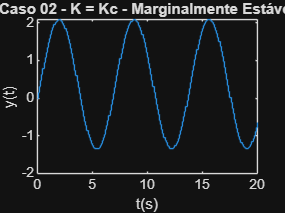

%% Situação 02 - K = Kc; 
K = Kc; 
Gf2 = K*Gd / (1 + K*Gd);
[y2, t] = step(Gf2, t);
figure
stairs(t, y2)
title('Caso 02 - K = Kc - Marginalmente Estável')
xlabel('t(s)')
ylabel('y(t)')

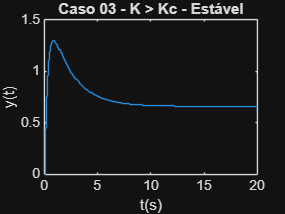

%% Situação 03 - K > Kc;
K = 100; 
Gf3 = K*Gd / (1 + K*Gd);
[y3, t] = step(Gf3, t);
figure
stairs(t, y3)
title('Caso 03 - K > Kc - Estável')
xlabel('t(s)')
ylabel('y(t)')

Questão (2)

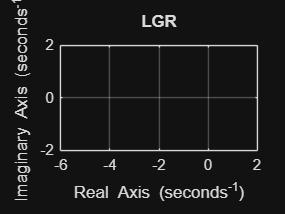

close all 
clear all 
clc 
Gd = tf([0.02268 0.02052], [1 -1.741 0.7408]);
rlocus(Gd);
zgrid
title('LGR')
axis equal 

Kc = margin(Gd)

Kc = 76.7657

Pelo comando Margin, Kc = 76.7657. Logo, pode-se avaliar a resposta ao degrau para as 3 situações possíveis: K = Kc, K < Kc e K > Kc. Com isso, tem-se o seguinte código:

%% Situação 01 - K < Kc
disp('Gráficos referentes à Atividade 04 - Questão 02')

Gráficos referentes à Atividade 04 - Questão 02


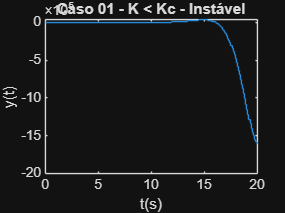

T = 0.1; 
t = 0:T:20;
K = 10; 
Gf1 = K*Gd / (1 + K*Gd);
[y1, t] = step(Gf1, t);
figure
stairs(t, y1)
title('Caso 01 - K < Kc - Instável')
xlabel('t(s)')
ylabel('y(t)')

%% Situação 02 - K = Kc; 
K = Kc; 
Gf2 = K*Gd / (1 + K*Gd)


Gf2 =
 
     1.741 s^3 - 1.456 s^2 - 1.453 s + 1.167
  ---------------------------------------------
  s^4 - 1.741 s^3 + 3.057 s^2 - 4.032 s + 1.716
 
Continuous-time transfer function.


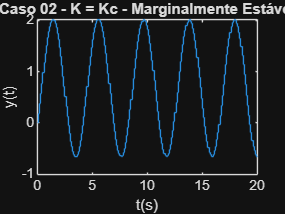

[y2, t] = step(Gf2, t);
figure
stairs(t, y2)
title('Caso 02 - K = Kc - Marginalmente Estável')
xlabel('t(s)')
ylabel('y(t)')

%% Situação 03 - K > Kc;
K = 125; 
Gf3 = K*Gd / (1 + K*Gd);


Gf3 =
 
      2.835 s^3 - 2.371 s^2 - 2.365 s + 1.9
  ---------------------------------------------
  s^4 - 0.647 s^3 + 2.142 s^2 - 4.945 s + 2.449
 
Continuous-time transfer function.


[y3, t] = step(Gf3, t);

y3 =          0
    0.2794
    0.5454
    0.7909
    1.0106
    1.2002
    1.3569
    1.4792
    1.5669
    1.6207
    1.6427
    1.6352
    1.6018
    1.5459
    1.4719


t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000
    1.0000
    1.1000
    1.2000
    1.3000
    1.4000


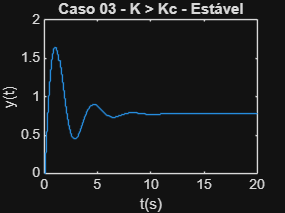

figure
stairs(t, y3)
title('Caso 03 - K > Kc - Estável')
xlabel('t(s)')
ylabel('y(t)')

## Atividade 05 - Valores de alpha

Instável para alpha=0.2
Instável para alpha=0.3
Instável para alpha=0.4
Instável para alpha=0.5
Instável para alpha=0.6
Instável para alpha=0.7
Instável para alpha=0.8
Instável para alpha=0.9
Instável para alpha=1


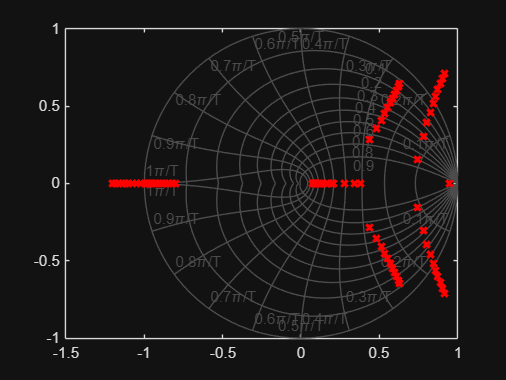

close all 
clear all
clc
for alpha = 0:0.1:1
    G = tf([1 0 0 0 0], [1 -0.7 -0.81 (0.67 + alpha) -0.12]);
    Gf = G / (1+G);
    figure(1);
    hold on;
    p = pole(Gf);
    if sum(abs(p)>1)>=1
        disp(['Instável para alpha=' num2str(alpha)])
    end
    plot(real(p), imag(p), 'X', 'LineWidth', 2, 'Color','red')
    zgrid
end

## Atividade 06 - Piloto Automático

help rlocfind

 rlocfind  Find root locus gains for a given set of roots.
 
    [K,POLES] = rlocfind(SYS)  is used for interactive gain 
    selection from the root locus plot of the SISO system SYS 
    generated by RLOCUS.  rlocfind puts up a crosshair cursor 
    in the graphics window which is used to select a pole location 
    on an existing root locus.  The root locus gain associated 
    with this point is returned in K and all the system poles for 
    this gain are returned in POLES.  
 
    [K,POLES] = rlocfind(SYS,P)  takes a vector P of desired root 
    locations and computes a root locus gain for each of these 
    locations (i.e., a gain for which one of the closed-loop roots
    is near the desired location).  The j-th entry of the vector K
    gives the computed gain for the location P(j), and the j-th 
    column of the matrix POLES lists the resulting closed-loop poles.
 
    See also  

Questão (1)

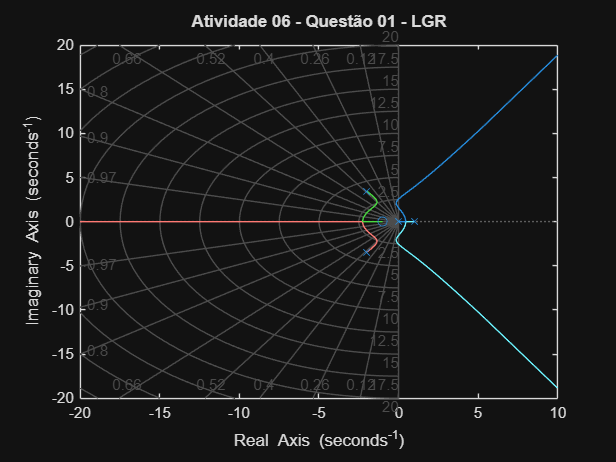

clear all;
close all; 
clc;
syms s
G_s = (s+1)/(s*(s-1)*(s^2+4*s+16));
[num, den] = numden(G_s);
num_G = sym2poly(num);
den_G = sym2poly(den);
G = tf(num_G, den_G);
rlocus(G)
sgrid
title('Atividade 06 - Questão 01 - LGR')

Questão (2)

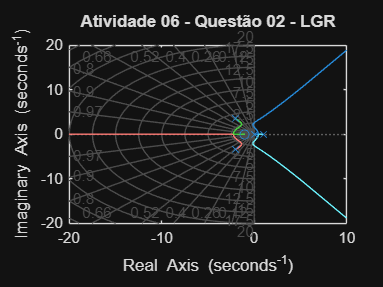

Select a point in the graphics window


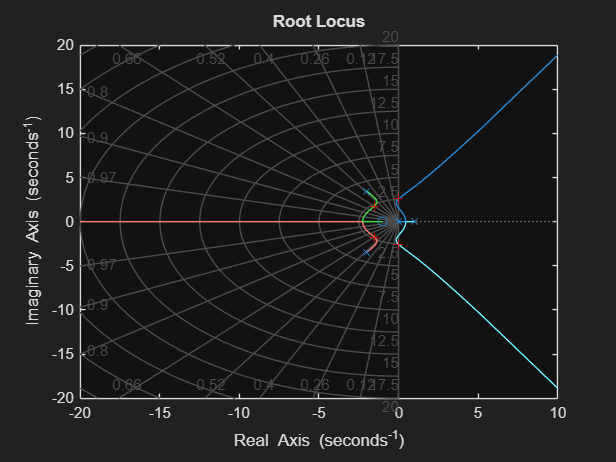

selected_point =      -25/434    +  280/107i  


K =     6863/191   


polos =       50/5927   + 1605/623i  
      50/5927   - 1605/623i  
   -1341/889    + 1171/661i  
   -1341/889    - 1171/661i  


syms s
G_s = (s+1)/(s*(s-1)*(s^2+4*s+16));
[num, den] = numden(G_s);
num_G = sym2poly(num);
den_G = sym2poly(den);
G = tf(num_G, den_G);
rlocus(G)
sgrid
title('Atividade 06 - Questão 02 - LGR')
[K, polos] = rlocfind(G)

Questão (3)

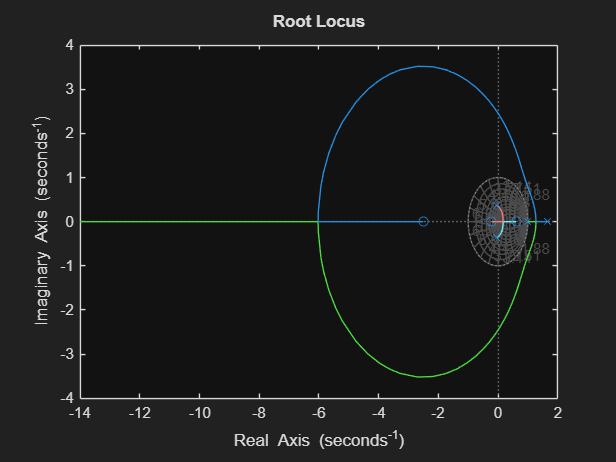

Ts = 0.5; 
Gd_zoh = c2d(G, Ts, 'zoh');
rlocus(Gd_zoh)
zgrid

Questão (4)

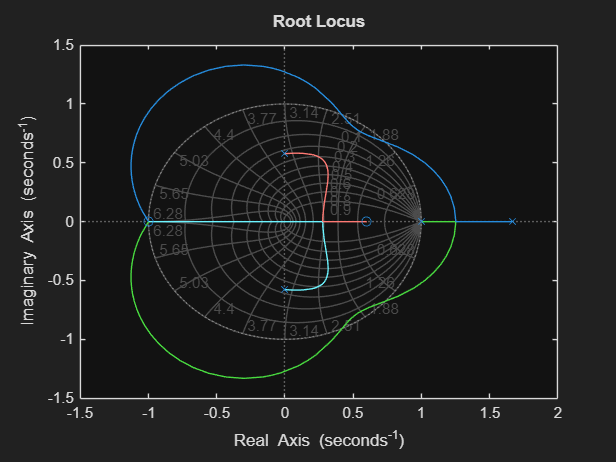

Gd_tustin = c2d(G, Ts, 'tustin');
rlocus(Gd_tustin)
zgrid